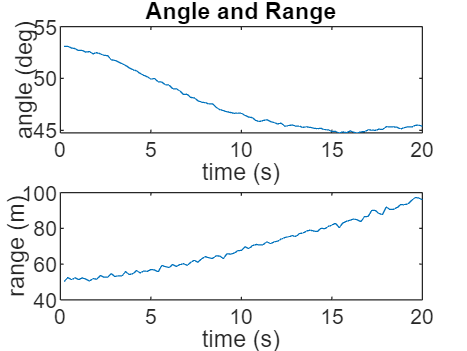

rng(2022);    % For repeatable results
dt = 0.2;     % seconds
simTime = 20; % seconds
tspan = 0:dt:simTime;
trueInitialState = [30; 1; 40; 1]; % [x;vx;y;vy]
initialCovariance = diag([100,1e3,100,1e3]);
processNoise = diag([0; .01; 0; .01]); % Process noise matrix

measureNoise = diag([2e-6;1]); % Measurement noise matrix. Units are m^2 and rad^2.

numSteps = length(tspan);
trueStates = NaN(4,numSteps);
trueStates(:,1) = trueInitialState;
estimateStates = NaN(size(trueStates));
measurements = NaN(2,numSteps);

for i = 2:length(tspan)
    if i ~= 1
        trueStates(:,i) = stateModel(trueStates(:,i-1),dt) + sqrt(processNoise)*randn(4,1);  
    end
    measurements(:,i) = measureModel(trueStates(:,i)) + sqrt(measureNoise)*randn(2,1);
end

figure(1)
plot(trueStates(1,1),trueStates(3,1),"r*",DisplayName="Initial Truth")
hold on
plot(trueStates(1,:),trueStates(3,:),"r",DisplayName="True Trajectory")
xlabel("x (m)")
ylabel("y (m)")
title("True Trajectory")
axis square

figure(2)
subplot(2,1,1)
plot(tspan,measurements(1,:)*180/pi)
xlabel("time (s)")
ylabel("angle (deg)")
title("Angle and Range")
subplot(2,1,2)
plot(tspan,measurements(2,:))
xlabel("time (s)")
ylabel("range (m)")

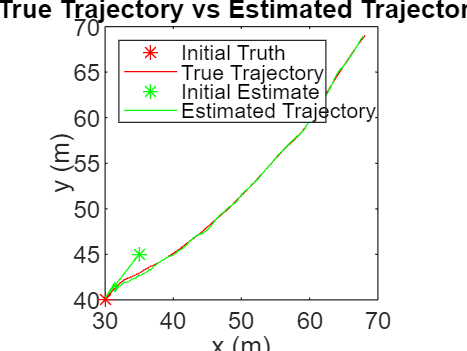


filter = trackingEKF(State=[35; 0; 45; 0],StateCovariance=initialCovariance, ...
    StateTransitionFcn=@stateModel,ProcessNoise=processNoise, ...
    MeasurementFcn=@measureModel);
estimateStates(:,1) = filter.State;

for i=2:length(tspan)
    predict(filter,dt);
    estimateStates(:,i) = correct(filter,measurements(:,i));
end
figure(1)
plot(estimateStates(1,1),estimateStates(3,1),"g*",DisplayName="Initial Estimate")
plot(estimateStates(1,:),estimateStates(3,:),"g",DisplayName="Estimated Trajectory")
legend(Location="northwest")
title("True Trajectory vs Estimated Trajectory")

function stateNext = stateModel(state)
    x1 = state(1)
    x2 = state(2)
    x3 = state(3)
    x4 = state(4)

    F = [
        0 1 0 0;
        0 0 0.0051*cos(x3)*sin(x3)*x4^4 + 0.4183*cos(x3) -0.0102*x4^3*cos(x3)^2;
        0 0 0 1;
        0 0 0 -40
    ]
    stateNext = F*state;
end

function z = measureModel(state)
    z = [1, 0, 0, 0; 0, 0, 1, 0]*state
end
